# RLC Simulink, Simscape, and Live Script Example

This example provides a basic template for how to connect live scripts with simulink models.  If they use Simscape or not, this example should work.

## Thumbnail of the Model

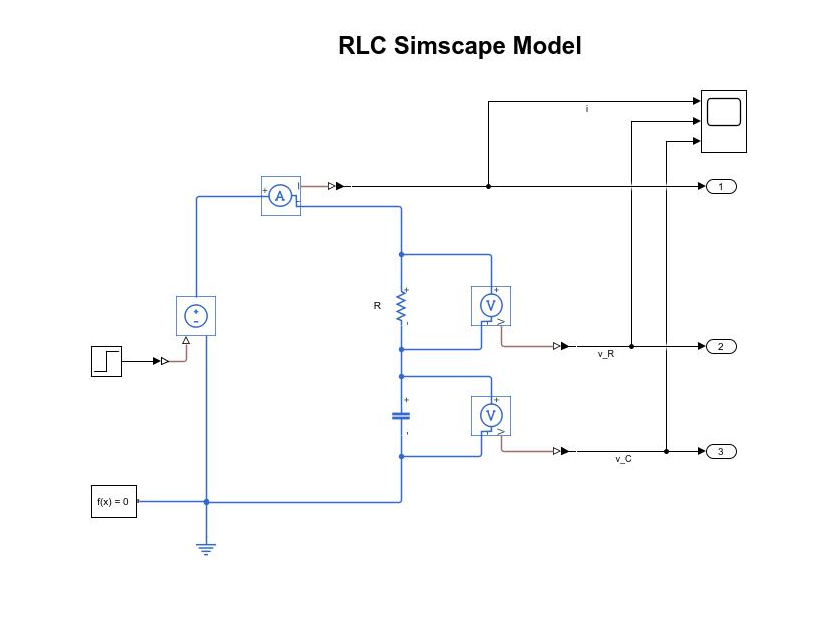

model = 'RLC_ssc';
[file,data] = SLML.GenerateModelImage(model);
imshow(data)

## Paramaterize the Model

% this is model specific

V0 =2; VF = 10;
R = 1; C = 0.0001;
n = 6;

tau = R*C; 
simTime = n*tau*2; 
stepTime = n*tau;

## Load and Simulate the Model

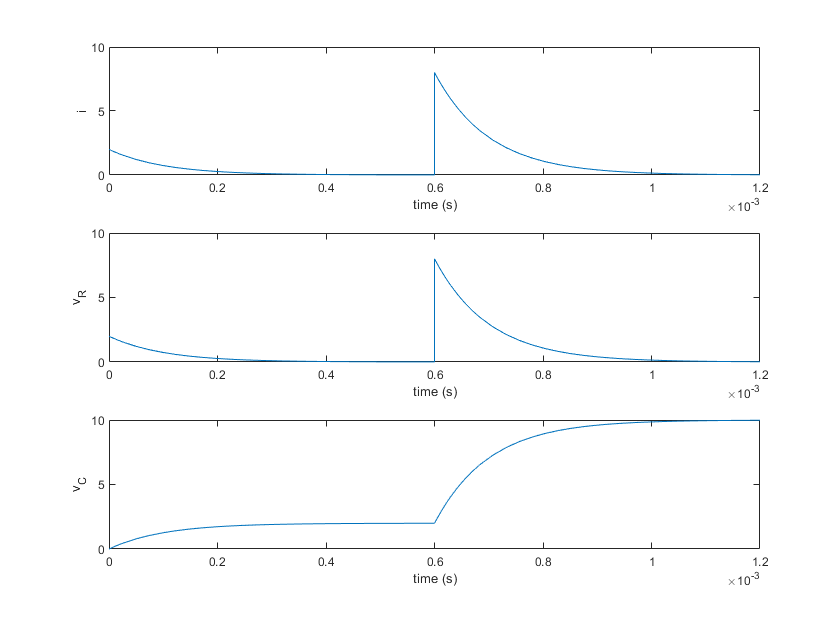

 

load_system(model);
out = sim(model);

% get all output values
nsig = out.yout.numElements;
for i = 1:nsig
    [t,data,name] = SLML.UnpackSig(out.yout{i});
    subplot(nsig,1,i)
    plot(t,data)
    xlabel('time (s)')
    ylabel(name)
end

## Open Signal Data Inspector

SLML.OpenDataInspector();
 

## Open Simulink Model

open(model);

 

## Open Simscape Explorer